# Aircraft Conflict Resolution

syms t x_circle y_circle

safe_radius = 5;
v = 5;
omega = 1;
phi = pi/2;
init_state = [15; -15];

v1 = v;
v2 = v;
omega_1 = omega;
omega_2 = omega;

r_turn = v/omega;       % turning radius
v_slope = v2/v1;        % slope of velocity seen from relative system

## State q1: cruise

% state q1: velocity
x_r_dot_q1 = -v1 + v2*cos(phi);
y_r_dot_q1 = v2*sin(phi);
phi_r_dot_q1 = 0;

state_q1_dot = [x_r_dot_q1; y_r_dot_q1]

state_q1_dot =     -5
     5



%state q1: position
x_r_q1 = int(x_r_dot_q1, t) + init_state(1);
y_r_q1 = int(y_r_dot_q1, t) + init_state(2);
phi_r = rad2deg(atan( y_r_dot_q1 / x_r_dot_q1));

state_q1 = [x_r_q1; y_r_q1]

$$state\_q1 = \left(\begin{array}{c} 15-5\,t\\ -15+5\,t \end{array}\right)$$

## State q2: manuver

C1 = -5;
C2 = -5;

% solutions of given differential equation
x_r_q2 = C1 * cos(t) + C2 * sin(t) + 5;
y_r_q2 = C1 * cos(t) - C2 * sin(t) + 5;

state_q2 = [x_r_q2; y_r_q2]

$$state\_q2 = \left(\begin{array}{c} 5-5\,\sin\left(t\right)-5\,\cos\left(t\right)\\ 5\,\sin\left(t\right)-5\,\cos\left(t\right)+5 \end{array}\right)$$


x_r_dot_q2 = -5 + y_r_q2;
y_r_dot_q2 = 5 - x_r_q2;

state_q2_dot = [x_r_dot_q2; y_r_dot_q2]

$$state\_q2\_dot = \left(\begin{array}{c} 5\,\sin\left(t\right)-5\,\cos\left(t\right)\\ 5\,\cos\left(t\right)+5\,\sin\left(t\right) \end{array}\right)$$


%fprintf("x_r_dot_q2 - diff(x_r_q2, t) == %f ", simplify(x_r_dot_q2 - diff(x_r_q2, t) ) )
%fprintf("y_r_dot_q2 - diff(y_r_q2, t) == %f ", simplify(y_r_dot_q2 - diff(y_r_q2, t) ) )

## Check for possibile collision

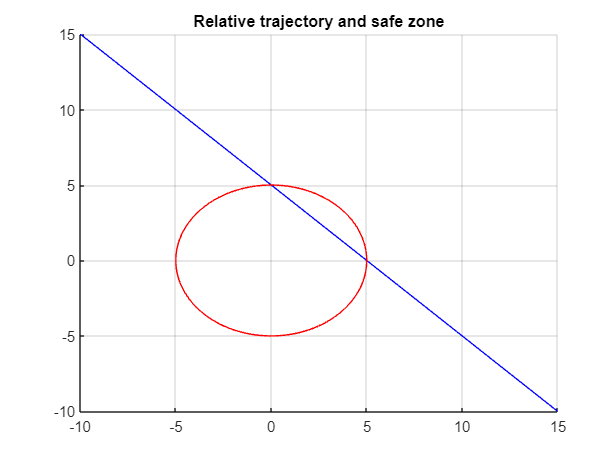

circle_eqn = safe_radius*[cos(t);sin(t)];

t_s = linspace(0, 5, 100);
t_q1 = linspace(0, 2*pi, 100);

state_q1_x_vals = double(subs(state_q1(1), t, t_s));
state_q1_y_vals = double(subs(state_q1(2), t, t_s));

circle_x_vals = subs(circle_eqn(1), t, t_q1);
circle_y_vals = subs(circle_eqn(2), t, t_q1);
 
figure;
hold on;
grid on;
title('Relative trajectory and safe zone')
plot(state_q1_x_vals, state_q1_y_vals, 'b')
plot(circle_x_vals, circle_y_vals, 'r')

eqn_circle_break = state_q1(1)^2 + state_q1(2)^2 - safe_radius^2;

time_break = solve(eqn_circle_break, t);

x1_break = double( subs(state_q1(1), t, time_break(1)) );
y1_break = double( subs(state_q1(2), t, time_break(1)) );
x2_break = double( subs(state_q1(1), t, time_break(2)) );
y2_break = double( subs(state_q1(2), t, time_break(2)) );

fprintf('t1 = %.2f, Punto: (%.2f, %.2f)\n', time_break(1), x1_break, y1_break);

t1 = 2.00, Punto: (5.00, 0.00)


fprintf('t2 = %.2f, Punto: (%.2f, %.2f)\n', time_break(2), x2_break, y2_break);

t2 = 3.00, Punto: (0.00, 5.00)


## Plot of zones

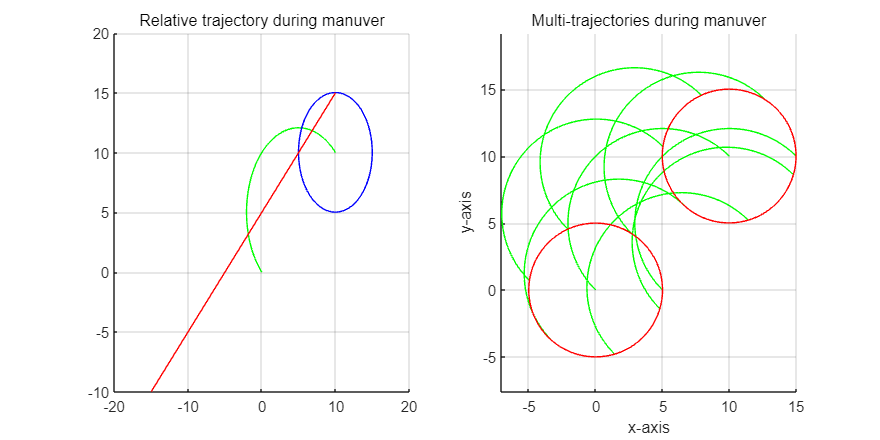


figure1=figure('Position', [100, 100, 800, 400]);

t_man = linspace(0, pi, 1000);
t_circle = linspace(0, 2*pi, 1000);

% Rotation angle and rotation matrix(
theta = 0; % -pi/2;
rot = [cos(theta), -sin(theta); sin(theta), cos(theta)];

theta_12 = pi/2;
rot_12 = [cos(theta_12), -sin(theta_12); sin(theta_12), cos(theta_12)];

% Solutions of differential equations
x_r_vals = -5 * cos(t_man) -5 * sin(t_man) + 5;
y_r_vals = -5 * cos(t_man) +5 * sin(t_man) + 5;

start_manuver_x = x_r_vals( length(x_r_vals) - 1);
start_manuver_y = y_r_vals( length(y_r_vals) - 1);

circle_x = start_manuver_x + safe_radius*cos(t_circle);
circle_y = start_manuver_y + safe_radius*sin(t_circle);


% Rotated points
rotated_points = rot * [x_r_vals; y_r_vals];
rotated_circle = rot * [circle_x; circle_y;];
rotated_straight = rot_12* [state_q1_x_vals; state_q1_y_vals];

% Plotting
subplot(1,2,1);
subtitle('Relative trajectory during manuver');
hold on;
grid on;
plot(rotated_points(1, :), rotated_points(2, :), 'g');
plot(rotated_circle(1,:) , rotated_circle(2,:) , 'b');
plot(rotated_straight(1,:) , rotated_straight(2,:), 'r')

for i=0:2*pi
    safe_x_r_vals = x_r_vals + safe_radius*cos(i);
    safe_y_r_vals = y_r_vals + safe_radius*sin(i);

    rotated_safe = rot*[safe_x_r_vals; safe_y_r_vals];

    %plot(rotated_safe(1,:) , rotated_safe(2,:) , 'c');
    
end

% Second plot
subplot(1, 2, 2);
hold on;
plot(rotated_points(1, :), rotated_points(2, :), 'g');
plot(rotated_circle(1, :), rotated_circle(2, :), 'r');

for i=0:2*pi
    safe_x_r_vals = x_r_vals + safe_radius*cos(i);
    safe_y_r_vals = y_r_vals + safe_radius*sin(i);

    rotated_safe = rot*[safe_x_r_vals; safe_y_r_vals];

    plot(rotated_safe(1,:) , rotated_safe(2,:) , 'g');
    
end

safe_circle_x = safe_radius * cos(t_circle);
safe_circle_y = safe_radius * sin(t_circle);
rotated_c_safe = rot * [safe_circle_x; safe_circle_y];
plot(rotated_c_safe(1, :), rotated_c_safe(2, :), 'r');
plot(rotated_circle(1,:) , rotated_circle(2,:) , 'r');

subtitle('Multi-trajectories during manuver');
xlabel('x-axis');
ylabel('y-axis');
grid on;
axis equal;
hold off;

## Compute time starting manuvers

eqn_circle_start = ( state_q1(1) - start_manuver_x)^2 + (state_q1(2) + start_manuver_y)^2 - safe_radius^2;

time_man = solve(eqn_circle_start, t);

x1 = double( subs(state_q1(1), t, time_man(1)) );
y1 = double( subs(state_q1(2), t, time_man(1)) );
x2 = double( subs(state_q1(1), t, time_man(2)) );
y2 = double( subs(state_q1(2), t, time_man(2)) );

fprintf('t1 = %.2f, Punto: (%.2f, %.2f)\n', time_man(1), x1, y1);

t1 = 0.00, Punto: (14.98, -9.98)


fprintf('t2 = %.2f, Punto: (%.2f, %.2f)\n', time_man(2), x2, y2);

t2 = 1.00, Punto: (10.02, -5.02)


## Result

fprintf("Initial relative position: (%.2f, %.2f)", init_state(1), init_state(2)) 

Initial relative position: (15.00, -10.00)

fprintf("Manuver disabled for t < %.2f  -> Aircraft 2 is to too far from Aircraft 1, manuver will be useless", time_man(2))

Manuver disabled for t < 1.00  -> Aircraft 2 is to too far from Aircraft 1, manuver will be useless

fprintf("Manuver enabled for %.2f < t < %.2f -> Aircraft 1 and 2 can perfom manuver succesully avoiding collins", time_man(2), time_break(1))

Manuver enabled for 1.00 < t < 2.00 -> Aircraft 1 and 2 can perfom manuver succesully avoiding collins

fprintf("Manuver forced for t = %.2f -> Aircraft must perform manuver or will collide", time_break(1))

Manuver forced for t = 2.00 -> Aircraft must perform manuver or will collide